# 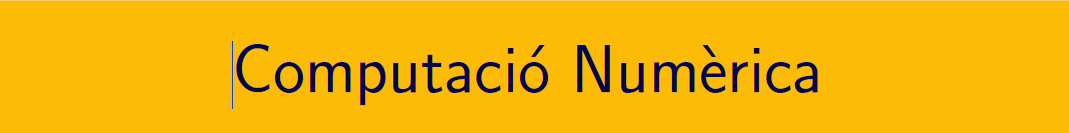

================================================================================

# Pràctica 10. Integració aproximada de funcions i dades.

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab9.pdf i en el document CN_full6.pdf, els podeu trobar en el campus virtual. 

## 1 APRENEM .....

### 1.1 MATLAB® - Trapezis

Consulta la documentació i exemples de [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) i l'exemple de [integració de dades numèriques](https://es.mathworks.com/help/matlab/math/integration-of-numeric-data.html)

Per al mètode de Simpson, podeu fer ús de l'expressió  $ S(f,h)=\displaystyle\frac{4}{3}T\left(f,\frac{h}{2}\right)-\frac{1}{3}T(f,h)$que relaciona la fórmula dels trapezis i la regla de Simpson. També podeu fer ús dels codis de [codis integració aproximada](http://www.math.mcgill.ca/gantumur/math578f09/?Matlab_files)

### 1.2 MATLAB® - Romberg

Podeu fer ús dels codis de Matlab File Exchange, [codis](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) 

### 1.3 MATLAB® - Integració adaptativa

%  quadgui(@(x)humps(x),0,1,1.0e-2)
integral(@(x)humps(x),0,1,'RelTol',1e-8,'AbsTol',1e-13)

## 2 PRACTIQUEM ....

### Pràctica 21. Aplicació per funcions.

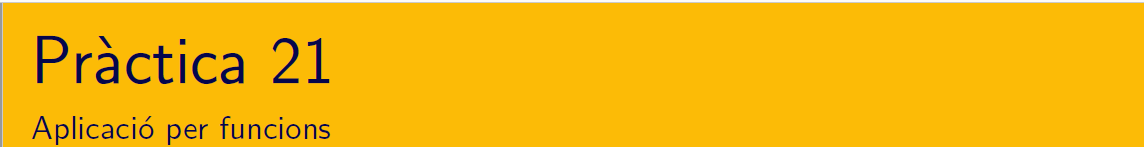

Scripts per avaluar integrals mitjançant la fórmula composta del rectangle, dels trapezis i de Simpson. Les dades has d'èsser `a`, `b`, n així com una function que avalui f(x) per a qualsevol $x\in[a,b]$ i el resultat un valor aproximat de $\int_a^b f(x)\ dx$ pel mètode aproximat. Verifiqueu els vostres codis amb el joc de proves de la pràctica 21. 

- 
$$I=\int_{1}^{2} \ln(x)\,dx\,= 2\ln(2)-1$$


format 
f = @(x) log(x);
a = 1; b = 2; k = 1:6;
ve = integral(f,a,b)

ve = 0.3863

% Métode del rectangle
my_midp(f,a,b,k);

    k       h         f(_)        error       xifres
    _    ________    _______    __________    ______

    1         0.5    0.39138     0.0050853      1   
    2        0.25    0.38759     0.0012939      2   
    3       0.125    0.38662      0.000325      3   
    4      0.0625    0.38638    8.1348e-05      3   
    5     0.03125    0.38631    2.0343e-05      4   
    6    0.015625     0.3863    5.0861e-06      4   



% Métode de Trapezis
my_trap(f,a,b,k);

    k       h         f(_)        error       xifres
    _    ________    _______    __________    ______

    1         0.5    0.37602      0.010275      1   
    2        0.25     0.3837     0.0025949      2   
    3       0.125    0.38564    0.00065045      2   
    4      0.0625    0.38613    0.00016272      3   
    5     0.03125    0.38625    4.0688e-05      4   
    6    0.015625    0.38628    1.0172e-05      4   



% Mètode de Simpson
my_simp(f,a,b,k);

    k       h         f(_)        error       xifres
    _    ________    _______    __________    ______

    1         0.5    0.38583    0.00045976      3   
    2        0.25    0.38626    3.4798e-05      4   
    3       0.125    0.38629    2.3177e-06      5   
    4      0.0625    0.38629    1.4744e-07      6   
    5     0.03125    0.38629    9.2576e-09      7   
    6    0.015625    0.38629    5.7927e-10      8   



% Mètode de Montecarlo
my_montecarlo(f,a,b,k);

    k      M       f(_)        error       xifres
    _    _____    _______    __________    ______

    1       10    0.23634       0.14995      0   
    2      100    0.35267      0.033621      1   
    3     1000    0.38722    0.00092667      2   
    4    10000    0.38505     0.0012427      2   
    5    1e+05    0.38627    2.2481e-05      4   
    6    1e+06    0.38637    7.0779e-05      3   



-     
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


f = @(x) 2./(1+x.^2);
a = 0; b = 1; k = 1:6;
ve = integral(f,a,b)

ve = 1.5708

% Métode del rectangle
my_midp(f,a,b,k);

    k       h         f(_)       error       xifres
    _    ________    ______    __________    ______

    1         0.5    1.5812       0.01038      1   
    2        0.25    1.5734     0.0026039      2   
    3       0.125    1.5714    0.00065104      2   
    4      0.0625     1.571    0.00016276      3   
    5     0.03125    1.5708     4.069e-05      4   
    6    0.015625    1.5708    1.0173e-05      4   



% Métode de Trapezis
my_trap(f,a,b,k);

    k       h         f(_)       error       xifres
    _    ________    ______    __________    ______

    1         0.5      1.55      0.020796      1   
    2        0.25    1.5656     0.0052081      1   
    3       0.125    1.5695     0.0013021      2   
    4      0.0625    1.5705    0.00032552      3   
    5     0.03125    1.5707     8.138e-05      3   
    6    0.015625    1.5708    2.0345e-05      4   



% Mètode de Simpson
my_simp(f,a,b,k);

    k       h         f(_)       error       xifres
    _    ________    ______    __________    ______

    1         0.5    1.5667     0.0041297       2  
    2        0.25    1.5708    1.2013e-05       4  
    3       0.125    1.5708    7.5566e-08       6  
    4      0.0625    1.5708    1.1825e-09       8  
    5     0.03125    1.5708    1.8478e-11      10  
    6    0.015625    1.5708    2.8866e-13      12  



% Mètode de Montecarlo
my_montecarlo(f,a,b,k);

    k      M       f(_)       error       xifres
    _    _____    ______    __________    ______

    1       10    1.6414      0.070575      0   
    2      100    1.5553      0.015468      1   
    3     1000    1.5741     0.0032587      2   
    4    10000     1.573     0.0022145      2   
    5    1e+05    1.5707    9.1184e-05      3   
    6    1e+06    1.5708    3.6394e-05      4   



- 
$$ I=\int_{0}^{\pi/4}{\cos}^2(x)\,dx\,={\left[ \frac{\sin(2x)}{4}+\frac{x}{2}\right]}_0^{\pi/4}$$


f = @(x) cos(x).^2;
a = 0; b = pi/4; k = 1:6;
ve = integral(f,a,b)

ve = 0.6427

% Métode del rectangle
my_midp(f,a,b,k);

    k       h         f(_)        error       xifres
    _    ________    _______    __________    ______

    1      0.3927    0.64924      0.006543      1   
    2     0.19635    0.64431     0.0016136      2   
    3    0.098175     0.6431    0.00040205      3   
    4    0.049087     0.6428    0.00010043      3   
    5    0.024544    0.64272    2.5101e-05      4   
    6    0.012272    0.64271     6.275e-06      4   



% Métode de Trapezis
my_trap(f,a,b,k);

    k       h         f(_)        error      xifres
    _    ________    _______    _________    ______

    1         0.5    0.44254      0.20016      0   
    2        0.25    0.61916     0.023542      1   
    3       0.125    0.62307     0.019626      1   
    4      0.0625    0.62405      0.01865      1   
    5     0.03125    0.64054    0.0021641      2   
    6    0.015625     0.6406     0.002103      2   



% Mètode de Simpson
my_simp(f,a,b,k);

    k       h         f(_)        error      xifres
    _    ________    _______    _________    ______

    1         0.5    0.29503      0.34767      0   
    2        0.25    0.56924     0.073463      0   
    3       0.125    0.62438      0.01832      1   
    4      0.0625    0.62437     0.018325      1   
    5     0.03125     0.6352     0.007497      1   
    6    0.015625    0.64062    0.0020827      2   



% Mètode de Montecarlo
my_montecarlo(f,a,b,k);

    k      M       f(_)        error       xifres
    _    _____    _______    __________    ______

    1       10    0.66179      0.019088      1   
    2      100    0.65405      0.011355      1   
    3     1000     0.6486     0.0058988      1   
    4    10000    0.64302    0.00031812      3   
    5    1e+05    0.64274    3.7421e-05      4   
    6    1e+06    0.64267    2.6204e-05      4   



### Pràctica 22. Aplicació dades discretes

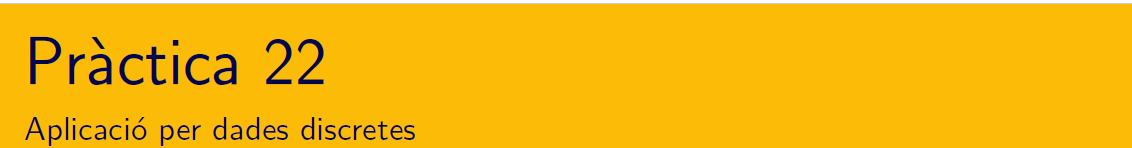

Calculeu $$\displaystyle\int_{1}^{1.8} f(x)\,dx$$ per les dades de la següent taula

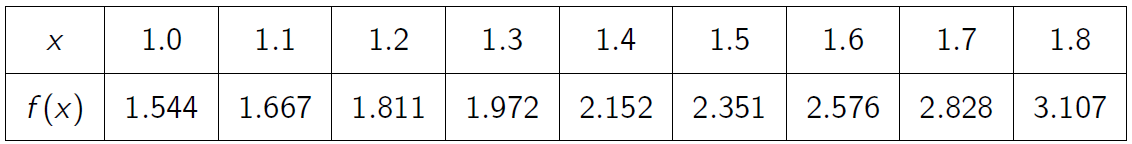

x = 1.0:0.1:1.8;
fx = [1.544 1.667 1.811 1.972 2.152 2.351 2.576 2.828 3.107];

- Representa gràficament les dades de la taula

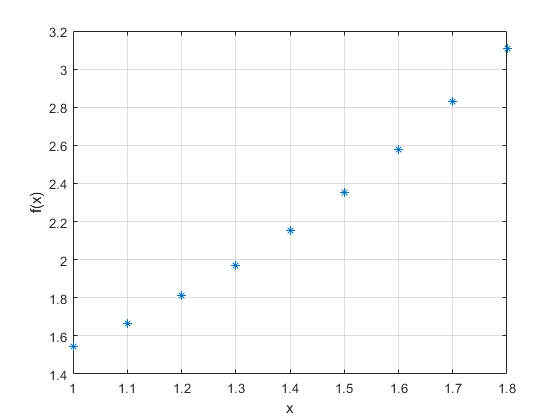

plot(x,fx,'*')
grid on
ylabel('f(x)')
xlabel('x')

- Explica l'estratègia i dona el resultat pel mètode dels trapezis prenent h=0.4,0.2 i 0.1

% h = 0.4;
X04 = [x(1) x(5) x(9)];
Y04 = [fx(1) fx(5) fx(9)];
I_04 = trapz(X04,Y04)

I_04 = 1.7910

% h = 0.2;
X02 = [x(1) x(3) x(5) x(7) x(9)];
Y02 = [fx(1) fx(3) fx(5) fx(7) fx(9)];
I_02 = trapz(X02,Y02)

I_02 = 1.7729

% h = 0.1;
I_01 = trapz(x,fx)

I_01 = 1.7683

- Explica l'estratègia i dona el resultat pel mètode de Simpson prenent h=0.4,0.2 i 0.1

% h = 0.4;
w = 4*ones(1,length(X04)-2);
w(2:2:end) = 2; w = [1 w 1];
h = 0.4;
S_04 = h/3*sum(w.*Y04)

S_04 = 1.7679

% h = 0.2;
w = 4*ones(1,length(X02)-2);
w(2:2:end) = 2; w = [1 w 1];
h = 0.2;
S_02 = h/3*sum(w.*Y02)

S_02 = 1.7669

% h = 0.1;
w = 4*ones(1,length(x)-2);
w(2:2:end) = 2; w = [1 w 1];
h = 0.1;
S_01 = h/3*sum(w.*fx)

S_01 = 1.7667

### Pràctica 23. MATLAB® - Integració adaptativa

### 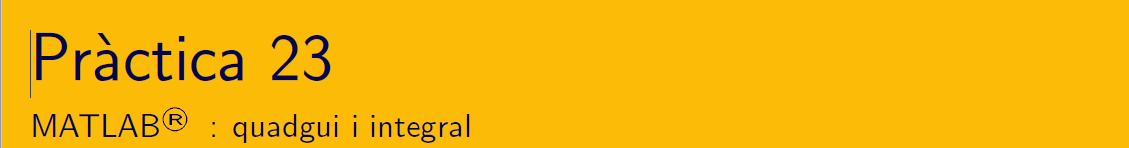

Feu ús de les rutines de MATLAB® per a calcular el valor de les següents integrals

- 
$$I=\int_{1}^{2} \ln(x)\,dx\,= 2\ln(2)-1$$


f = @(x) log(x);
quadgui(f,1,2,1.0e-2)
integral(f,1,2,'RelTol',1e-8,'AbsTol',1e-13)

-     
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


f = @(x) cos(x).^2;
quadgui(f,1,2,1.0e-2)
integral(f,1,2,'RelTol',1e-8,'AbsTol',1e-13)

- 
$$ I=\int_{0}^{\pi/4}{\cos}^2(x)\,dx\,={\left[ \frac{\sin(2x)}{4}+\frac{x}{2}\right]}_0^{\pi/4}$$


f = @(x) cos(x).^2;
quadgui(f,1,2,1.0e-2)
integral(f,1,2,'RelTol',1e-8,'AbsTol',1e-13)

### Pràctica 24. Mètode de Romberg

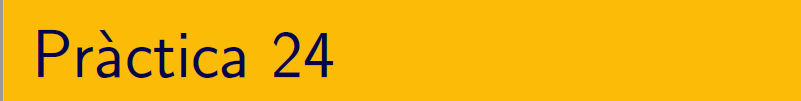

- Calculeu $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,\,=\frac{\pi}{2}$  fent ús del métode dels trapezia per $ h=\frac{1}{2^k},\ \ 0\leq k\leq 5.$ Quants decimals correctes s'obtenen?

f = @(x) 2./(1+x.^2);
ve = integral(f,0,1)

ve = 1.5708

my_trap(f,0,1,0:5);

    k       h        f(_)       error       xifres
    _    _______    ______    __________    ______

    0          1       1.5      0.070796      0   
    1        0.5      1.55      0.020796      1   
    2       0.25    1.5656     0.0052081      1   
    3      0.125    1.5695     0.0013021      2   
    4     0.0625    1.5705    0.00032552      3   
    5    0.03125    1.5707     8.138e-05      3   



- Calculeu $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,\,=\frac{\pi}{2}$  pel mètode de romberg, quants decimals correctes s'obtenen?

f = @(x) 2./(1+x.^2);
[r, h] = romberg(f,0,1,6);
disp(array2table([h', r],'VariableNames',{'h','T1','T2','T3','T4','T5','T6'}));

       h         T1        T2        T3        T4        T5        T6  
    _______    ______    ______    ______    ______    ______    ______

          1       1.5         0         0         0         0         0
        0.5      1.55    1.5667         0         0         0         0
       0.25    1.5656    1.5708    1.5711         0         0         0
      0.125    1.5695    1.5708    1.5708    1.5708         0         0
     0.0625    1.5705    1.5708    1.5708    1.5708    1.5708         0
    0.03125    1.5707    1.5708    1.5708    1.5708    1.5708    1.5708



ERT = [(0:5)',h',tril(abs(r-ve))];
taula = array2table(ERT,'VariableNames',{'k','h','ER_1','ER_2','ER_3','ER_4','ER_5','ER_6'}); disp(taula)

    k       h          ER_1          ER_2          ER_3          ER_4          ER_5          ER_6   
    _    _______    __________    __________    __________    __________    __________    __________

    0          1      0.070796             0             0             0             0             0
    1        0.5      0.020796     0.0041297             0             0             0             0
    2       0.25     0.0052081    1.2013e-05     0.0002625             0             0             0
    3      0.125     0.0013021    7.5566e-08    7.2027e-07    3.4349e-06             0             0
    4     0.0625    0.00032552    1.1825e-09    3.7764e-09    7.5965e-09     5.844e-09             0
    5    0.03125    

ERT = [(0:5)',h',tril(fix(-log10(2*abs(r-ve))))];
taula = array2table(ERT,'VariableNames',{'k','h','xifres R_1','xifres R_2','xifres R_3','xifres R_4','xifres R_5','xifres R_6'});
fprintf('\n%15s\n\n', 'Xifres significatives Romberg'); disp(taula)

Xifres significatives Romberg

    k       h       xifres R_1    xifres R_2    xifres R_3    xifres R_4    xifres R_5    xifres R_6
    _    _______    __________    __________    __________    __________    __________    __________

    0          1        0              0            0              0             0             0    
    1        0.5        1              2            0              0             0             0    
    2       0.25        1              4            3              0             0             0    
    3      0.125        2              6            5              5             0             0    
    4     0.0625        3              8            8              7             7        

### Pràctica 25. Mètodes de Montecarlo

- Calculeu $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,\,=\frac{\pi}{2}$  per fent ús d'una mostra de nombres aleatòris, quants decimals correctes s'obtenen? Preneu mostres de tamany $10^i\,\ i=2,3,4,5,6\,.$

f = @(x) 2./(1+x.^2);
my_montecarlo(f,0,1,1:6);

    k      M       f(_)       error       xifres
    _    _____    ______    __________    ______

    1       10    1.5214      0.049376      1   
    2      100    1.5526      0.018204      1   
    3     1000    1.5654     0.0053601      1   
    4    10000    1.5719     0.0011248      2   
    5    1e+05    1.5704    0.00034984      3   
    6    1e+06    1.5707    9.3804e-05      3   



- Calculeu l'àrea de l'el·lipse d'equació $13x^2+34xy+25y^2\leq 1$ per a $(x,y)\in [-1,1]\times[-1,1]$. Preneu mostres de tamany $10^i\,\ i=2,3,4,5,6\,.$Quants decimals correctes s'obtenen?  (valor $\pi/6$)

% TODO
f = @(x,y) 13.*x.^2 + 34.*x.*y + 25*y.^2;
a = -1; b = 1; R = [];
for i = 2:6
    m = 10^i;
    aprox = my_montecarloHitMiss(f,a,b,m);
    R = [R; i, m, aprox, abs((pi./6)-aprox)];
end
taula = array2table(R,'VariableNames',{'i','m','aprox','error'}); disp(taula)

    i      m       aprox       error   
    _    _____    _______    __________

    2      100       0.52     0.0035988
    3     1000      0.512      0.011599
    4    10000     0.5628      0.039201
    5    1e+05    0.51688     0.0067188
    6    1e+06    0.52303    0.00057078



`Document preparat per M. Àngela Grau Gotés - 5 de maig de 2021`